### Circuito Linea de Tranmision

clear all
Start_Freq=0.1E9;
End_Freq=2E9;
Step=1000;
Z0=50;

netlist_TLfile='NetlistSpice\LineaTransmision2.net';
netlistCell=Netlist2CellArray(netlist_TLfile)

netlistCell = 6×7 cell array
    {'TL1'}    {'N003'}    {'N005'}    {'TL'}    {[        45]}    {[45]}    {[1.0000e+09]}
    {'L1' }    {'N001'}    {'N003'}    {'L' }    {[1.0000e-08]}    {[ 0]}    {[         0]}
    {'L2' }    {'N005'}    {'N002'}    {'L' }    {[1.0000e-08]}    {[ 0]}    {[         0]}
    {'TL2'}    {'N004'}    {'N002'}    {'TL'}    {[        60]}    {[45]}    {[1.0000e+09]}
    {'R1' }    {'N003'}    {'N004'}    {'R' }    {[        75]}    {[ 0]}    {[         0]}
    {'TL3'}    {'N005'}    {'0'   }    {'TL'}    {[        45]}    {[45]}    {[1.0000e+09]}



% Metodo Objeto Circuito Matlab
SMatlab4=SParametersFromNetlist(netlistCell,Start_Freq,End_Freq,Step,Z0);

TL =   txlineElectricalLength: ElectricalLength element

                  Name: 'ElectricalLength'
                    Z0: 45
            LineLength: 0.7854
    ReferenceFrequency: 1.0000e+09
           Termination: 'NotApplicable'
              StubMode: 'NotAStub'
              NumPorts: 2
             Terminals: {'p1+'  'p2+'  'p1-'  'p2-'}


TL =   txlineElectricalLength: ElectricalLength element

                  Name: 'ElectricalLength'
                    Z0: 60
            LineLength: 0.7854
    ReferenceFrequency: 1.0000e+09
           Termination: 'NotApplicable'
              StubMode: 'NotAStub'
              NumPorts: 2
             Terminals: {'p1+'  'p2+'  'p1-'  'p2-'}


TL =   txlineElectricalLength: ElectricalLength element

                  Name: 'ElectricalLength'
                    Z0: 45
            LineLength: 0.7854
    ReferenceFrequency: 1.0000e+09
           Termination: 'NotApplicable'
              StubMode: 'NotAStub'
              NumPorts: 2
             Terminals: {'p1+'  'p2+'  'p1-'  'p2-'}


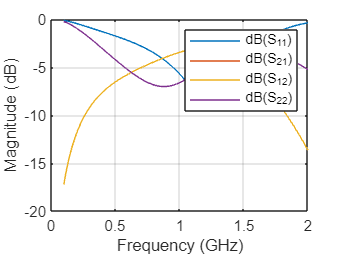

rfplot(SMatlab4);


% Metodo circuito equivalente
nuevo_Netlist=NetlistCircuitoEquivalente(netlistCell)

newType = 'SSC'

nuevo_Netlist = 10×7 cell array
    {'L1'   }    {'N001'}    {'N003'}    {'L'    }    {[1.0000e-08]}    {[     0]}    {[         0]}
    {'L2'   }    {'N005'}    {'N002'}    {'L'    }    {[1.0000e-08]}    {[     0]}    {[         0]}
    {'R1'   }    {'N003'}    {'N004'}    {'R'    }    {[        75]}    {[     0]}    {[         0]}
    {'SSC'  }    {'N005'}    {'0'   }    {'SSC'  }    {[        45]}    {[    45]}    {[1.0000e+09]}
    {'TL_Y1'}    {'N003'}    {'N005'}    {'TL_Y1'}    {[        45]}    {[0.7854]}    {[1.0000e+09]}
    {'TL_Y2'}    {'N003'}    {'0'   }    {'TL_Y2'}    {[        45]}    {[0.7854]}    {[1.0000e+09]}
    {'TL_Y3'}    {'N005'}    {'0'   }    {'TL_Y3'}    {[        45]}    {[0.7854]}    {[1.0000e+09]}
    {'TL_Y1'}    {'N004'}    {'N002'}    {'TL_Y1'}    {[        60]}    {[0.7854]}    {[1.0000e+09]}
    {'TL_Y2'}    {'N004'}    {'0'   }    {'TL_Y2'}    {[        60]}    {[0.7854]}    {[1.0000e+09]}
    {'TL_Y3'}    {'N002'}    {'0'   }    {'TL_Y3'}    {[   

Matriz_Z=Z_parameters(nuevo_Netlist, Start_Freq, End_Freq, Step, 2);
Matriz_S=z2s(Matriz_Z,50);

freq=linspace(Start_Freq, End_Freq, Step);
SParamsObject=sparameters(Matriz_S,freq,50);
rfplot(SParamsObject)


% ----- INICIO----------


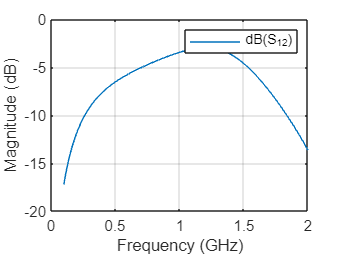


rfplot(SMatlab4,1,2)

rfplot(SParamsObject,1,2)